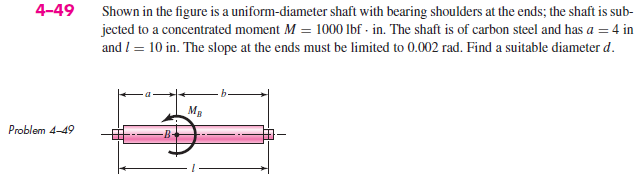

# assumptions

old_assum = assumptions;
clearassum;

# given

u = symunit;
dy_allow = 0.002*u.rad;
D = sym('D', 'positive');

# beam

b = beam;
b = b.add('reaction', 'force', 'R1', 0);
b = b.add('applied', 'moment', 1000*u.lbf*u.in, 4*u.in);
b = b.add('reaction', 'force', 'R2', 10*u.in);
b.L = 10*u.in;

# section properties

b.E = 30e6*u.psi;
b.I = sympi*(D/2)^4/4;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} \frac{x\,\left(x^{2}+8\,{\mathrm{in}}^{2}\right)}{28125\,{\text{D}}^{4}\,\pi }\,{\mathrm{in}}^{2} & \text{ if }x\leq 4\,\mathrm{in}\\ \frac{\left(x-10\,\mathrm{in}\right)\,\left(x^{2}-20\,x\,\mathrm{in}+48\,{\mathrm{in}}^{2}\right)}{28125\,{\text{D}}^{4}\,\pi }\,{\mathrm{in}}^{2} & \text{ if }4\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{3\,x^{2}+8\,{\mathrm{in}}^{2}}{28125\,{\text{D}}^{4}\,\pi }\,{\mathrm{in}}^{2} & \text{ if }x\leq 4\,\mathrm{in}\\ \frac{3\,x^{2}-60\,x\,\mathrm{in}+248\,{\mathrm{in}}^{2}}{28125\,{\text{D}}^{4}\,\pi }\,{\mathrm{in}}^{2} & \text{ if }4\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 100\,x\,\mathrm{lbf} & \text{ if }x\leq 4\,\mathrm{in}\\ 100\,\left(x-10\,\mathrm{in}\right)\,\mathrm{lbf} & \text{ if }4\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = 100\,\mathrm{lbf}$$

w

$$w(x) = 0$$

addvar(y);

# reactions

R1 = r.R1

$$R1 = 100\,\mathrm{lbf}$$

R2 = r.R2

$$R2 = -100\,\mathrm{lbf}$$

# shear and moment diagram

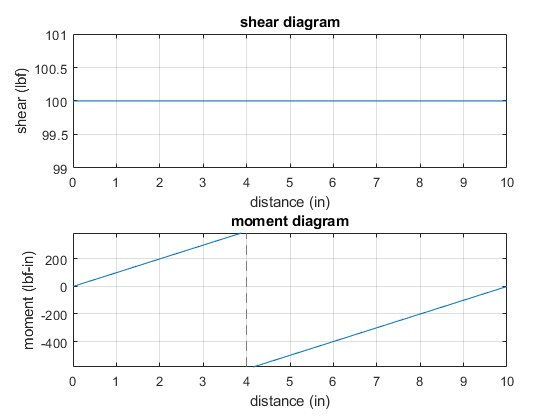

beam.shear_moment(m, v, [0 b.L], {'lbf' 'in'});

# diameter design for the left end

dy1(D) = abs(dy(0))

$$dy1(D) = \frac{8}{28125\,{\text{D}}^{4}\,\pi }\,{\mathrm{in}}^{4}$$

D1 = simplify(solve(dy_allow/u.rad == dy1, D));
D1_vpa = vpa(D1, 3) %#ok

$$D1\_vpa = 0.461\,\mathrm{in}$$

# diameter design for the right end

dy2(D) = abs(dy(b.L))

$$dy2(D) = \frac{52}{28125\,{\text{D}}^{4}\,\pi }\,{\mathrm{in}}^{4}$$

D2 = simplify(solve(dy_allow/u.rad == dy2, D));
D2_vpa = vpa(D2, 3) %#ok

$$D2\_vpa = 0.737\,\mathrm{in}$$

clear D1_vpa D2_vpa;

# diameter limit for the ends

dy_ends = [dy1; dy2]*u.rad;
D_vals = [D1; D2];
valid_D = [all(isAlways(dy_ends(D1) <= dy_allow)); ...
           all(isAlways(dy_ends(D2) <= dy_allow))];
D_limit = D_vals(valid_D);
D_limit_vpa = vpa(D_limit, 3) %#ok

$$D\_limit\_vpa = 0.737\,\mathrm{in}$$

setassum(old_assum, 'clear');
clear dy_ends D_vals valid_D D_limit_vpa old_assum;